clear all
close all
format long


**System parameters**

params.M_m = 0.251;
params.m = 0.179;
params.i = 0.792e-4;
params.I = 2.592e-4;
params.R = 0.06;
params.rho = 0.024;
params.g = 9.81;

[ a, b_0, b_1, c, d, g, R ] = params2p(params);


params.servo_0 = 0;
params.servo_1 = 0;
params.servo_2 = 0;
params.servo_3 = 0.1;
params.servo_4 = 0;
params.servo_5 = 0;
params.servo_6 = 0;


**Verification of **$\alpha \beta \gamma$** coefficients**

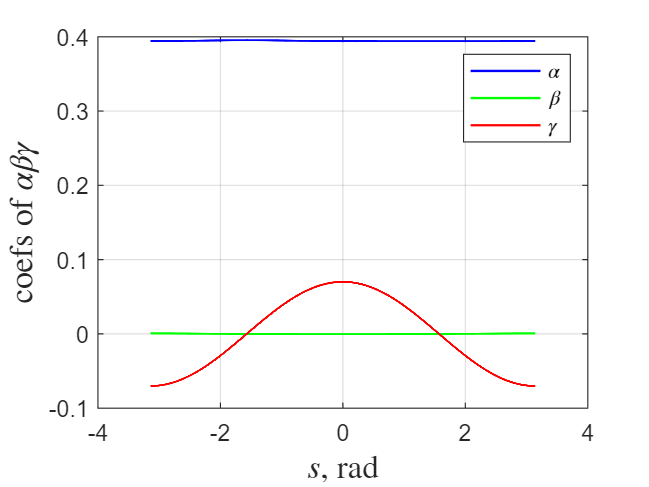

s = -pi:0.001:pi;

A = [];
B = [];
G = [];
for i = 1 : length(s)
    [AA,BB,GG] = plot_abg(s(i), params);
    A = [A, AA];
    B = [B, BB];
    G = [G, GG];
end

figure()
plot(s,A,'-b',LineWidth=1.0)
hold on
plot(s,B,'-g',LineWidth=1.0)
plot(s,G,'-r',LineWidth=1.0)
grid on
xlabel('$s$, rad',Interpreter='latex',FontSize=14)
ylabel('coefs of $\alpha \beta \gamma$',Interpreter='latex',FontSize=14)
legend('$\alpha$','$\beta$','$\gamma$','Interpreter','latex')

## Integration itself

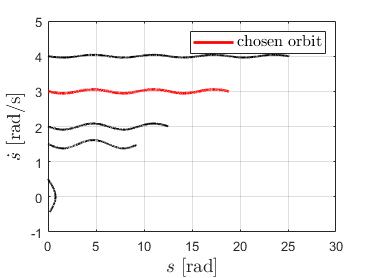

options = odeset('RelTol', 1e-12, 'AbsTol', 1e-16);
t_end = 2 * pi;
y_0 = [ 0; 2 ];
y_01 = [ 0; 3 ];
y_02 = [ 0; 4 ];


[ T1,  Y1 ] = ode89(@(t,y) abg_rhs(t,y,params), [0:0.001:t_end], y_0, options);
[ T, Y ] = ode89(@(t,y) abg_rhs(t,y,params), [0:0.001:t_end], y_01, options);
[ T2, Y2 ]= ode89(@(t,y) abg_rhs(t,y,params), [0:0.001:t_end], y_02, options);

[ T3, Y3 ] = ode89(@(t,y) abg_rhs(t,y,params), [0:0.001:t_end], [0; 0.5], options);
[ T4, Y4 ] = ode89(@(t,y) abg_rhs(t,y,params), [0:0.001:t_end], [ 0; 1.5 ], options);

% [ T00, Y00 ] = ode89(@(t,y) rhs(t,y,params), [0:0.00001:t_end], y_01, options);

S = Y(:,1);
V = Y(:,2);

figure()
plot(S, V, '-r', LineWidth = 2.0)
hold on
plot(Y1(:,1), Y1(:,2), '-k', LineWidth=1.5)
plot(Y2(:,1), Y2(:,2), '-k', LineWidth=1.5)
plot(Y3(:,1), Y3(:,2), '-k', LineWidth=1.5)
plot(Y4(:,1), Y4(:,2), '-k', LineWidth=1.5)
% plot(Y00(:,1), Y00(:,2), '-b', LineWidth=1.5)

xlabel('$s$ [rad]',Interpreter='latex',FontSize=14)
ylabel('$\dot{s}$ [rad/s]',Interpreter='latex',FontSize=14)
% axis([-2.1 -2.07 0.75 2])
grid on
legend("chosen orbit", '', '', '', '', 'FontSize', 12, 'interpreter', 'latex')

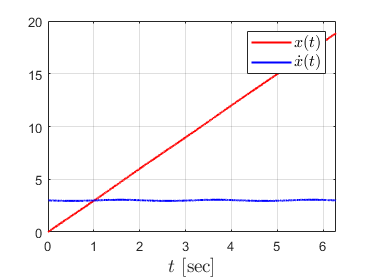


X = zeros(2,length(T));

for i = 1 : length(T)
    [ Q, dQ, ddQ ] = servo(S(i), params);
    X(:,i) = [ Q(1); dQ(1) * V(i) ];
end

figure()
plot(T,X(1,:),'r',LineWidth=1.5)
hold on
plot(T,X(2,:),'b',LineWidth=1.5)
xlabel('$t$ [sec]',Interpreter='latex',FontSize=14)
% ylabel('$\dot{s}$ [rad/s]',Interpreter='latex',FontSize=14)
grid on
legend('$x(t)$','$\dot{x}(t)$','FontSize',12,'interpreter','latex')

clear T1 T2 T3 T4 Y1 Y2 Y3 Y4 y_01 y_02 y_0

## **Find signle periodic trajectory**

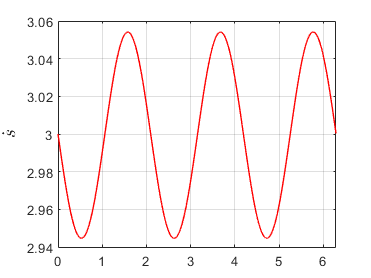

figure()
plot(T, V, '-r', LineWidth=1.0)
ylabel('$\dot{s}$',Interpreter='latex',FontSize=14)
grid on

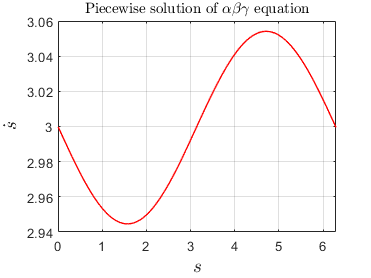


% t_idx = (T >= 2.7355) & (T <= 3.7302); %2.5
% t_idx = (T >= 2.9528) & (T <= 4.0267); %1,5
% t_idx = (T >= 3.0160) & (T <= 4.11824); %1.0
t_idx = (T >= 0) & (T <= 2.1); %1.0

T = T(t_idx);
T = T - T(1);
S = S(t_idx);
V = V(t_idx);

T = T(3:end-2);
T = T - T(1);
S = S(3:end-2);
V = V(3:end-2);


figure()
plot(S, V,'-r', LineWidth=1.0)
xlabel('$s$',Interpreter='latex',FontSize=14)
ylabel('$\dot{s}$',Interpreter='latex',FontSize=14)
% axis([-2.1 -2.07 0.75 2])
grid on
title('Piecewise solution of $\alpha \beta \gamma$ equation','Interpreter','latex')

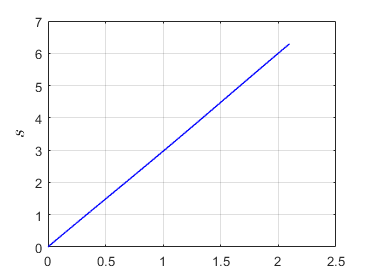


figure()
plot(T,S,'-b', LineWidth=1.0)
ylabel('$s$',Interpreter='latex',FontSize=14)
grid on

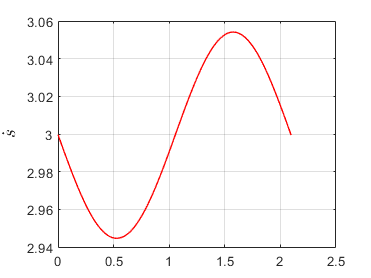

figure()
plot(T,V,'-r', LineWidth=1.0)
ylabel('$\dot{s}$',Interpreter='latex',FontSize=14)
grid on

## **Spline interpolation**

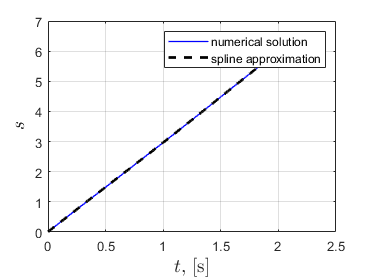

st = csaps(T,S);
vt = csaps(T,V);


% spline verification
t = 0 : 0.001 : T(end);

figure()
plot(T, S,'-b', LineWidth=1.0)
hold on
plot(t, ppval(st,t),'--k', LineWidth=2.0)
ylabel('$s$',Interpreter='latex',FontSize=14)
xlabel('$t$, [s]',Interpreter='latex',FontSize=14)
grid on
% axis([ 0 t(end) -2.25 -1.85])
legend('numerical solution','spline approximation')

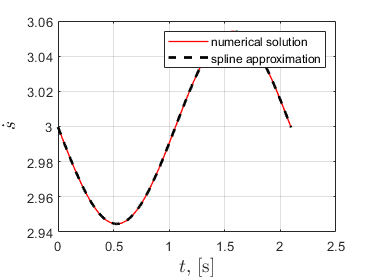


figure()
plot(T, V,'-r', LineWidth=1.0)
hold on
plot(t, ppval(vt,t),'--k', LineWidth=2.0)
ylabel('$\dot{s}$',Interpreter='latex',FontSize=14)
xlabel('$t$, [s]',Interpreter='latex',FontSize=14)
grid on
% axis([ 0 t(end) -2.5 2.5])
legend('numerical solution','spline approximation')


ddst = fnder(st, 2);
dvt  = fnder(vt, 1);

T_per = T(end)

T_per =    2.096000000000000


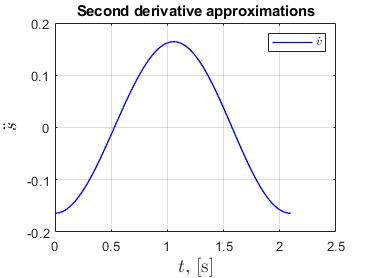

clear T Y



figure()
plot(t,ppval(dvt, t),'-b', LineWidth=1.0)
hold on
% plot(t,ppval(ddst, t),'-r', LineWidth=1.0)
ylabel('$\ddot{s}$',Interpreter='latex',FontSize=14)
xlabel('$t$, [s]',Interpreter='latex',FontSize=14)
% axis([-2.1 -2.07 0.75 2])
grid on
title("Second derivative approximations")
legend('$\dot{v}$','Interpreter','latex')

## **Find nominal control**

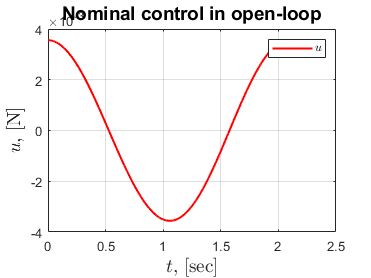

U = zeros(1,length(t));

for i = 1 : length(t)
    U(i) = find_u_eq(ppval(st,t(i)), ppval(vt,t(i)), ppval(dvt,t(i)), params);
end

pu = csaps(t,U);

figure()
plot(t,U,'-r',LineWidth=1.5)

grid on
xlabel('$t$, [sec]',Interpreter='latex',FontSize=14)
ylabel('$u$, [N]',Interpreter='latex',FontSize=14)
title('Nominal control in open-loop',FontSize=14);
legend('$u$','Interpreter','latex')

## Simulation of full dynamics with nominal control

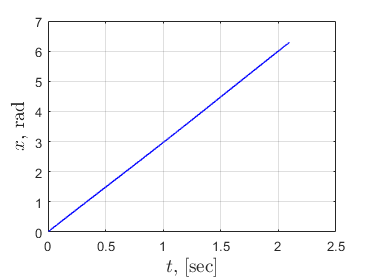

s0  = ppval(st, t(1));
ds0 = ppval(vt, t(1));

[ Q0, dQ0, ddQ0 ] = servo(s0, params);
y0 = [ Q0; dQ0 .* ds0];

options_normal = odeset('RelTol', 1e-12, 'AbsTol', 1e-16);
[ TT, YY ] = ode89(@(t,y) true_system(t,y,pu,T_per,params), [0 T_per], y0, options_normal);

figure()
plot(TT, YY(:,1),'-b',LineWidth=1.0)
grid on
xlabel('$t$, [sec]',Interpreter='latex',FontSize=14)
ylabel('$x$, rad',Interpreter='latex',FontSize=14)

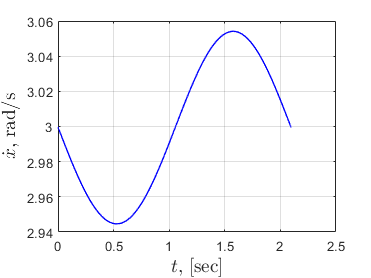


figure()
plot(TT, YY(:,3),'-b',LineWidth=1.0)
grid on
xlabel('$t$, [sec]',Interpreter='latex',FontSize=14)
ylabel('$\dot{x}$, rad/s',Interpreter='latex',FontSize=14)

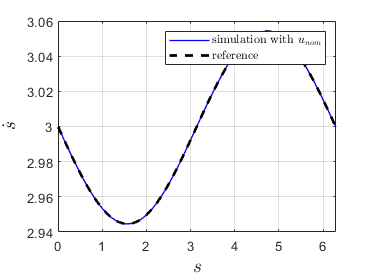


figure()
plot(YY(:,1), YY(:,3),'-b',LineWidth=1.0)
grid on
hold on
plot(S,V,'--k',LineWidth=2.0)
xlabel('$s$',Interpreter='latex',FontSize=14)
ylabel('$\dot{s}$',Interpreter='latex',FontSize=14)
legend('simulation with $u_{nom}$','reference','Interpreter','latex')

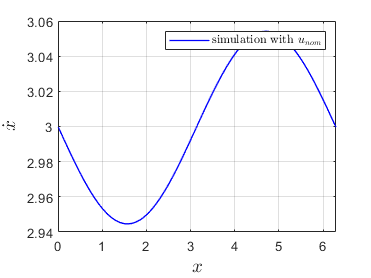


figure()
plot(YY(:,1), YY(:,3),'-b',LineWidth=1.0)
grid on
hold on
xlabel('$x$',Interpreter='latex',FontSize=14)
ylabel('$\dot{x}$',Interpreter='latex',FontSize=14)
% xline(s_sing,'--k',LineWidth=0.5)
legend('simulation with $u_{nom}$','Interpreter','latex')

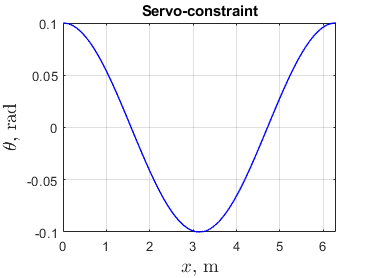


figure()
plot(YY(:,1), YY(:,2),'-b',LineWidth=1.0)
grid on
hold on
xlabel('$x$, m',Interpreter='latex',FontSize=14)
ylabel('$\theta$, rad',Interpreter='latex',FontSize=14)
title('Servo-constraint')


clear TT YY


## Trajectory Stabilization

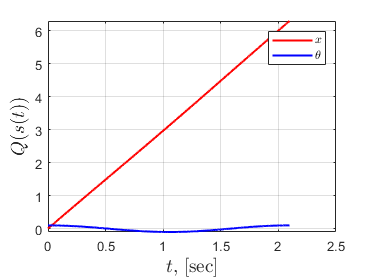

t_sample = 0.001;
t_sample_cr = 0.0005;

t = make_sampling(t_sample,t_sample_cr, T_per);

[ X, dX ] = from_MG_to_X(t, st, vt, dvt, params);

% X  = [  X,  X(:,1) ];
% dX = [ dX, dX(:,1) ];
% t = [t, t(end) + t(end) - t(end-1)];
% T_per = t(end)

figure()
plot(t, X(1,:), '-r',LineWidth=1.5)
hold on
plot(t, X(2,:), '-b',LineWidth=1.5)
grid on
xlabel('$t$, [sec]',Interpreter='latex',FontSize=14)
ylabel('$Q(s(t))$',Interpreter='latex',FontSize=14)
legend('$x$','$\theta$','Interpreter','latex')

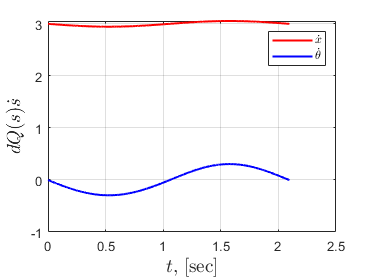


figure()
plot(t, dX(1,:), '-r',LineWidth=1.5)
hold on
plot(t, dX(2,:), '-b',LineWidth=1.5)
grid on
xlabel('$t$, [sec]',Interpreter='latex',FontSize=14)
ylabel('$dQ(s)\dot{s}$',Interpreter='latex',FontSize=14)
legend('$\dot{x}$','$\dot{\theta}$','Interpreter','latex')


X_ref = [ csaps(t,X(1,:)); csaps(t,X(2,:)); csaps(t,X(3,:)); csaps(t,X(4,:)) ];
dX_ref = [ csaps(t,dX(1,:)); csaps(t,dX(2,:)); csaps(t,dX(3,:)); csaps(t,dX(4,:)) ];


**Step 2**: Searching for $E(t) \in \mathbf{R}^{n \times n-1}$

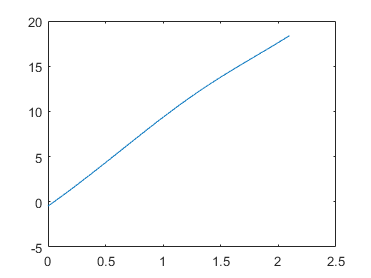

% define projection matrix P
% P_proj = eye(4);
P_proj = diag([1 0 1 0]);

% P_proj = diag([ 0, , 0, 0 ]);
% P_proj(3,3) = 0.2;
% P_proj(4,4) = 0.2;


% V(t)
VV = from_dX_to_V(t, dX, P_proj);

pv1 = csaps(t,VV(1,:));
pv2 = csaps(t,VV(2,:));
pv3 = csaps(t,VV(3,:));
pv4 = csaps(t,VV(4,:));

PV = [ pv1; pv2; pv3; pv4 ];

% dV/dt
dpv1 = fnder(pv1,1);
dpv2 = fnder(pv2,1);
dpv3 = fnder(pv3,1);
dpv4 = fnder(pv4,1);

DPV = [ dpv1; dpv2; dpv3; dpv4 ];

check_tran = zeros(1,length(t));

for i = 1 : length(t)

    check_tran(i) = from_t_to_vector4(t(i), X_ref)' * P_proj * from_t_to_vector4(t(i), dX_ref); 

end

figure()
plot(t,check_tran)

clear t



v1 = from_t_to_vector4(0,PV);
v2 = [0 1 0 0]';
R = get_R_matrix_from_v(v1,v2)

R =     0.0030   -0.9985    0.0546         0
    0.9985         0   -0.0547         0
    0.0546    0.0547    0.9970         0
         0         0         0    1.0000



% (R * v1)'

R_0 = R';

options = odeset('RelTol', 1e-12, 'AbsTol', 1e-16);
[ T, R ] = ode89(@(t, y) rhs(t, y, PV, DPV), [ 0:t_sample: T_per], reshape(R_0,16,1), options);

% R = nR;
R_0

R_0 =     0.0030    0.9985    0.0546         0
   -0.9985         0    0.0547         0
    0.0546   -0.0547    0.9970         0
         0         0         0    1.0000


R_1 = reshape(R(end,:)', 4, 4)

R_1 =     0.0030    0.9985    0.0546         0
   -0.9985         0    0.0547         0
    0.0546   -0.0547    0.9970         0
         0         0         0    1.0000



P = zeros(4, 4*length(T));



E_mod = zeros(4, 3 * length(T));


for i = 1 : length(T)
    P(:, (1 + 4 * (i - 1)) : (4 * i)) = reshape(R(i,:)', 4, 4) * expm( (T(i)/T_per) * logm(R_1' * R_0) );
    E_mod(:, 1 + 3*(i-1): 3*i) = P(:, (1 + 4 * (i - 1)) : (4 * i)) * [ zeros(1,3); eye(3) ];
end

% T1     = [ T(1:end-1) - T_per; T(1:end-1); T(1:end) + T_per ];
% E_mod1 = [ E_mod(:, 1:end-3 ), E_mod(:,1:end-3), E_mod ];
T1     = [ T(1 : end - 13) - T_per; T(12 : end - 12); T(12 : end) + T_per ];
E_mod1 = [ E_mod(:, 1 : end - 3 * 13 ), E_mod(:, 1 + 3 * 11 : end - 3 * 12), E_mod(:, 1 + 3 * 11 : end) ];

size(E_mod1, 2)/3

ans =         6244


length(T1)

ans =         6244


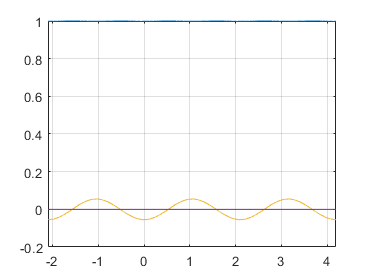



figure()
plot(T1, E_mod1(1, 1 : 3 : end))
hold on
plot(T1, E_mod1(2, 1 : 3 : end))
plot(T1, E_mod1(3, 1 : 3 : end))
plot(T1, E_mod1(4, 1 : 3 : end))
grid on

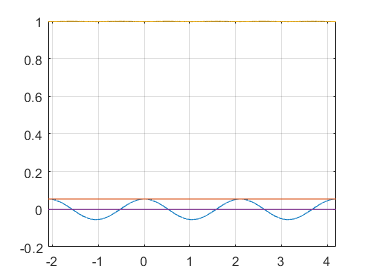



figure()
plot(T1, E_mod1(1, 2 : 3 : end))
hold on
plot(T1, E_mod1(2, 2 : 3 : end))
plot(T1, E_mod1(3, 2 : 3 : end))
plot(T1, E_mod1(4, 2 : 3 : end))
grid on

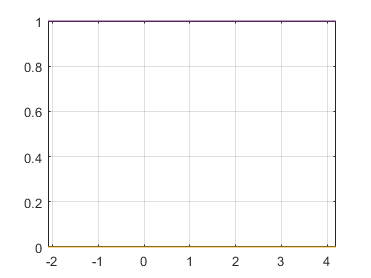


figure()
plot(T1, E_mod1(1, 3 : 3 : end))
hold on
plot(T1, E_mod1(2, 3 : 3 : end))
plot(T1, E_mod1(3, 3 : 3 : end))
plot(T1, E_mod1(4, 3 : 3 : end))
grid on

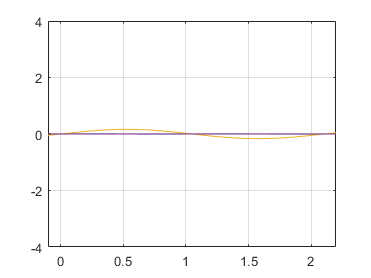



E_mod_s1 = [ csaps(T1,E_mod1(1,1:3:end)); csaps(T1,E_mod1(2,1:3:end)); csaps(T1,E_mod1(3,1:3:end)); csaps(T1,E_mod1(4,1:3:end)) ];
E_mod_s2 = [ csaps(T1,E_mod1(1,2:3:end)); csaps(T1,E_mod1(2,2:3:end)); csaps(T1,E_mod1(3,2:3:end)); csaps(T1,E_mod1(4,2:3:end)) ];
E_mod_s3 = [ csaps(T1,E_mod1(1,3:3:end)); csaps(T1,E_mod1(2,3:3:end)); csaps(T1,E_mod1(3,3:3:end)); csaps(T1,E_mod1(4,3:3:end)) ];

dE_mod_s1 = [ fnder(E_mod_s1(1), 1); fnder(E_mod_s1(2), 1); fnder(E_mod_s1(3), 1); fnder(E_mod_s1(4), 1) ];
dE_mod_s2 = [ fnder(E_mod_s2(1), 1); fnder(E_mod_s2(2), 1); fnder(E_mod_s2(3), 1); fnder(E_mod_s2(4), 1) ];
dE_mod_s3 = [ fnder(E_mod_s3(1), 1); fnder(E_mod_s3(2), 1); fnder(E_mod_s3(3), 1); fnder(E_mod_s3(4), 1) ];

dE_mod_s1_imp = zeros(4,length(T1));
dE_mod_s2_imp = zeros(4,length(T1));
dE_mod_s3_imp = zeros(4,length(T1));

for i = 1 : length(T1)
    dE_mod_s1_imp(:, i) = from_t_to_vector4(T1(i), dE_mod_s1);
    dE_mod_s2_imp(:, i) = from_t_to_vector4(T1(i), dE_mod_s2);
    dE_mod_s3_imp(:, i) = from_t_to_vector4(T1(i), dE_mod_s3);
end

figure()
plot(T1,dE_mod_s1_imp)
grid on
hold on
% xline(T_per,'--k',LineWidth=0.5)
axis([-0.1 T_per + 0.1 -4 4])

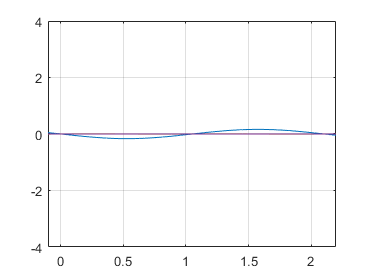


figure()
plot(T1,dE_mod_s2_imp)
grid on
hold on
% xline(T_per,'--k',LineWidth=0.5)
axis([-0.1 T_per + 0.1 -4 4])

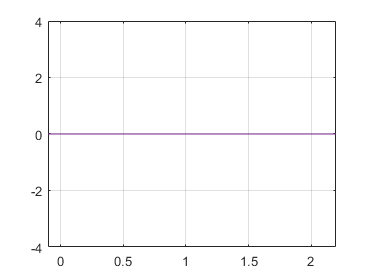


figure()
plot(T1,dE_mod_s3_imp)
hold on
grid on
% xline(T_per,'--k',LineWidth=0.5)
axis([-0.1 T_per + 0.1 -4 4])

**Step 3: **

**Transversal linearization**

syms w real
syms q_1 q_2 q_3 q_4 real
ddq = for_linear([ q_1 q_2 q_3 q_4 ]',params);

J = [ diff(ddq(1), q_1), diff(ddq(1), q_2), diff(ddq(1), q_3), diff(ddq(1), q_4);
      diff(ddq(2), q_1), diff(ddq(2), q_2), diff(ddq(2), q_3), diff(ddq(2), q_4);
      diff(ddq(3), q_1), diff(ddq(3), q_2), diff(ddq(3), q_3), diff(ddq(3), q_4);
      diff(ddq(4), q_1), diff(ddq(4), q_2), diff(ddq(4), q_3), diff(ddq(4), q_4) ]


J_fcn = matlabFunction(J)

J_fcn = function_handle with value:
    @(q_2,q_4)reshape([0.0,0.0,0.0,0.0,0.0,0.0,((cos(q_2).*6.162053220360456e+35-q_4.^2.*cos(q_2).*8.675184183459925e+33-cos(q_2).^2.*2.00546822989913e+36+sin(q_2).^2.*2.00546822989913e+36).*(-1.302083333333333e+2))./(cos(q_2).*1.635781202312812e+37-cos(q_2).^2.*2.661862138309031e+37+8.820050827655941e+37)+(sin(q_2).*1.635781202312812e+37-cos(q_2).*sin(q_2).*5.323724276618062e+37).*(sin(q_2).*-6.162053220360456e+35+q_4.^2.*sin(q_2).*8.675184183459925e+33+cos(q_2).*sin(q_2).*2.00546822989913e+36).*1.0./(cos(q_2).*1.635781202312812e+37-cos(q_2).^2.*2.661862138309031e+37+8.820050827655941e+37).^2.*1.302083333333333e+2,((cos(q_2).*4.026341592849162e+36-q_4.^2.*cos(q_2).*1.5703499542203e+33+q_4.^2.*cos(q_2).^2.*5.11077530555334e+33-q_4.^2.*sin(q_2).^2.*5.11077530555334e+33).*(-5.208333333333333e+3))./(cos(q_2).*1.635781202312812e+37-cos(q_2).^2.*2.661862138309031e+37+8.820050827655941e+37)-(sin(q_2).*1.635781202312812e+37-cos(q_2).*sin(q_2).*5.32372427661

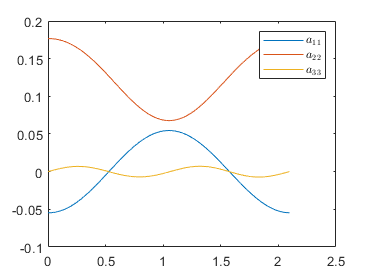


AA = zeros(3, 3 * length(T));
JJ = zeros(4, 4 * length(T));
BB = zeros(3, length(T));

for i = 1 : length(T)

    [ A, B ] = transv_linear(T(i), from_t_to_vector4(T(i), X_ref), E_mod_s1, E_mod_s2, E_mod_s3, dE_mod_s1, dE_mod_s2, dE_mod_s3, J_fcn, P_proj, params);
    y = from_t_to_vector4(T(i), X_ref);
    JJ(:, 1 + 4 * (i-1) : 4 * i) = J_fcn(y(2),y(4));
    AA(:, 1 + 3 * (i-1) : 3 * i) = A;
    BB(:, i) = B;
    
end

% AA = [ AA, AA(:,1:3)];
% BB = [ BB, BB(:,1)];

figure()
plot(T, AA(1, 1 : 3 : end))
hold on
plot(T, AA(2, 2 : 3 : end))
plot(T, AA(3, 3 : 3 : end))
legend('$a_{11}$','$a_{22}$','$a_{33}$','Interpreter','latex')

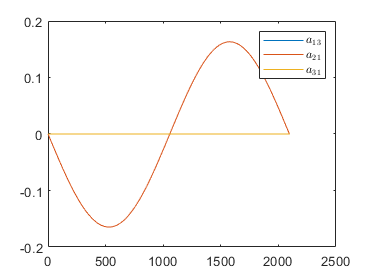


figure()
plot(AA(1,3:3:end))
hold on
plot(AA(2,1:3:end))
plot(AA(3,1:3:end))
legend('$a_{13}$','$a_{21}$','$a_{31}$','Interpreter','latex')

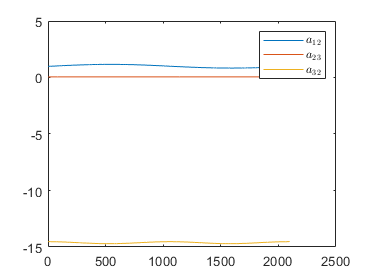


figure()
plot(AA(1,2:3:end))
hold on
plot(AA(2,3:3:end))
plot(AA(3,2:3:end))
legend('$a_{12}$','$a_{23}$','$a_{32}$','Interpreter','latex')

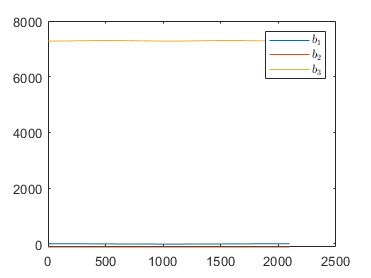


figure()
plot(BB(1,:))
hold on
plot(BB(2,:))
plot(BB(3,:))

legend('$b_{1}$','$b_{2}$','$b_{3}$','Interpreter','latex')

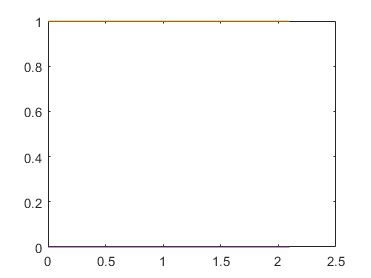



figure()
plot(T, JJ(1, 1 : 4 : end))
hold on
plot(T, JJ(1, 2 : 4 : end))
plot(T, JJ(1, 3 : 4 : end))
plot(T, JJ(1, 4 : 4 : end))

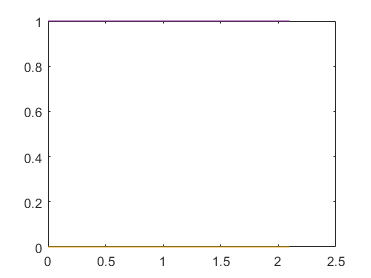



figure()
plot(T, JJ(2, 1 : 4 : end))
hold on
plot(T, JJ(2, 2 : 4 : end))
plot(T, JJ(2, 3 : 4 : end))
plot(T, JJ(2, 4 : 4 : end))

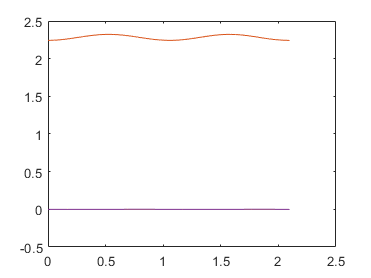


figure()
plot(T, JJ(3, 1 : 4 : end))
hold on
plot(T, JJ(3, 2 : 4 : end))
plot(T, JJ(3, 3 : 4 : end))
plot(T, JJ(3, 4 : 4 : end))

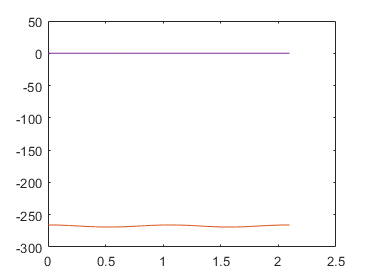


figure()
plot(T, JJ(4, 1 : 4 : end))
hold on
plot(T, JJ(4, 2 : 4 : end))
plot(T, JJ(4, 3 : 4 : end))
plot(T, JJ(4, 4 : 4 : end))

**Step 4: **

**Controller design for **$\dot{\mathbf{\xi}}=\mathbf{A}(t) \mathbf{\xi} + \mathbf{B}(t)\bar{u}$

P = sdpvar(3,3,'symmetric','real');

w = 2 * pi / T_per;
Q = 1 * diag([1,1,1]);
R = 0.1;
M = 40;

for j = 1:M
    P = [P; sdpvar(3,3,'sy','co')];
end

PP = zeros(3);
DP = zeros(3);
i = sqrt(-1);
L = [];

for j = 0 : length(T) - 1
    for k = 1:M
        PP = PP + exp(i*(-k)*w*T(j+1)) * conj( P(1+3*k:3*k + 3, 1:3) ) + exp(i*k*w*T(j+1))*P(1+3*k:3*k + 3, 1:3);
        DP = DP + (i*(-k)*w)*exp(i*(-k)*w*T(j+1)) * conj( P(1+3*k:3*k + 3, 1:3) ) + (i*k*w)*exp(i*k*w*T(j+1)) * P(1+3*k:3*k + 3, 1:3);
    end
    
    PP = PP + P(1:3,1:3);
    L11 = DP + PP * AA( :, (1 + 3*j):(3 + 3*j) ) + AA( :, (1 + 3*j):(3 + 3*j) )' * PP + Q; L12 = PP * BB( :, j+1 );
    L21 = BB( :, j+1 )' * PP;
    L22 = R;
    L = [ L, [L11 L12; L21 L22] >= 0 ];
    PP = zeros(3);
    DP = zeros(3);
end

F = trace(P(1:3,1:3));
optimize(L, -F);


 num. of constraints = 486
 dim. of sdp    var  = 8388,   num. of sdp  blk  = 2097
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.2e+05|2.3e+04|1.7e+09| 6.500700e+04  0.000000e+00| 0:0:01| chol  1  1 
 1|0.989|0.960|2.5e+03|9.5e+02|5.7e+07| 4.436033e+04  1.758785e+03| 0:0:02| chol  2  2 
 2|1.000|0.929|2.0e-03|6.7e+01|4.3e+06| 5.290450e+04 -2.475033e+03| 0:0:02| chol  2  2 
 3|1.000|0.991|9.2e-04|6.4e-01|9.1e+04| 5.117730e+04 -6.449273e+01| 0:0:03| chol  2  2 
 4|1.000|1.000|3.7e-04|8.1e-03|8.4e+03| 8.217133e+03 -4.094492e+01| 0:0:04| chol  2  2 
 5|0.959|1.000|2.9e-05|8.8e-04|3.5e+02| 3.115835e+02 -3.781744e+0

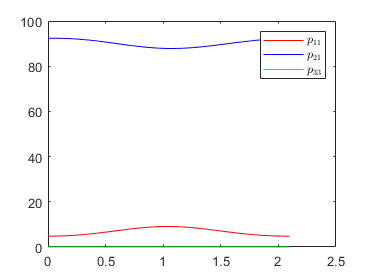

P_s = value(P);

PP = zeros(3);
DP = zeros(3);
P_final = [];

for j = 0 : length(T) - 1
    for k = 1:M
        PP = PP + exp(i*(-k)*w*T(j+1)) * conj( P_s(1+3*k:3*k + 3, 1:3) ) + exp(i*k*w*T(j+1)) * P_s(1+3*k:3*k + 3, 1:3);
        DP = DP + (i*(-k)*w)*exp(i*(-k)*w*T(j+1)) * conj( P_s(1+3*k:3*k + 3, 1:3) ) + (i*k*w)*exp(i*k*w*T(j+1)) * P_s(1+3*k:3*k + 3, 1:3);
    end
    PP = PP + P_s(1:3,1:3);
    P_final = [P_final; PP];
    PP = zeros(3);
    DP = zeros(3);
end


figure()
plot(T(1:end), P_final(1:3:end,1),'-r')
hold on
plot(T(1:end), P_final(2:3:end,2),'-b')
plot(T(1:end), P_final(3:3:end,3),'-g')
legend('$p_{11}$','$p_{21}$','$p_{33}$','Interpreter','latex')

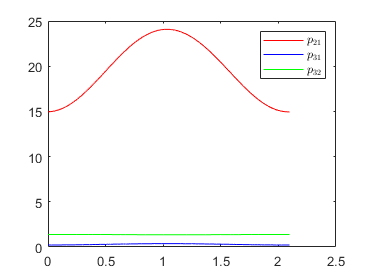


figure()
plot(T(1:end), P_final(2:3:end,1),'-r')
hold on
plot(T(1:end), P_final(3:3:end,1),'-b')
plot(T(1:end), P_final(3:3:end,2),'-g')
legend('$p_{21}$','$p_{31}$','$p_{32}$','Interpreter','latex')

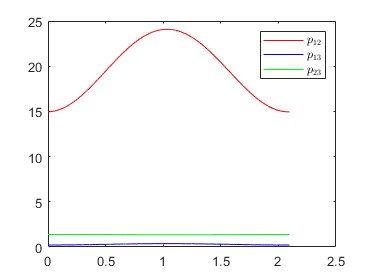


figure()
plot(T(1:end), P_final(1:3:end,2),'-r')
hold on
plot(T(1:end), P_final(1:3:end,3),'-b')
plot(T(1:end), P_final(2:3:end,3),'-g')
legend('$p_{12}$','$p_{13}$','$p_{23}$','Interpreter','latex')

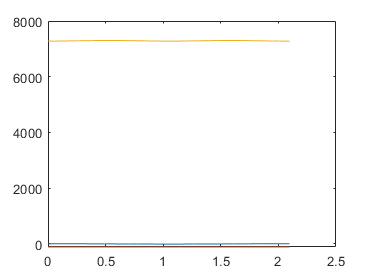



N = length(T);
K_stab = zeros(N,3);

for i = 1 : length(T)
   
    K_stab(i,1:3) = - (1 / R) * (BB(:,i))' * P_final(1 + 3 * (i - 1) : 3 * i, 1 : 3) ;

end

figure()
plot(T,BB)

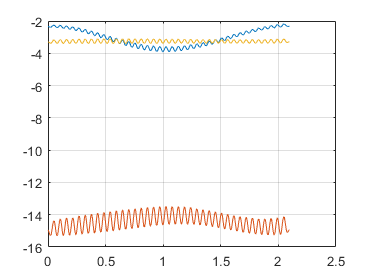



figure()
plot(T,K_stab(:,1))
hold on
plot(T,K_stab(:,2))
plot(T,K_stab(:,3))
grid on

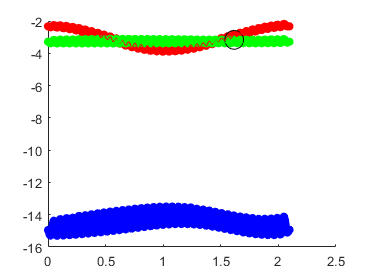



k_1 = spline(T,K_stab(:,1));
k_2 = spline(T,K_stab(:,2));
k_3 = spline(T,K_stab(:,3));


%% saving P_{+}(t) as spline
p_11 = spline(T,P_final(1:3:end,1));
p_12 = spline(T,P_final(1:3:end,2));
p_13 = spline(T,P_final(1:3:end,3));

p_21 = spline(T,P_final(2:3:end,1));
p_22 = spline(T,P_final(2:3:end,2));
p_23 = spline(T,P_final(2:3:end,3));

p_31 = spline(T,P_final(3:3:end,1));
p_32 = spline(T,P_final(3:3:end,2));
p_33 = spline(T,P_final(3:3:end,3));


figure()
scatter(T,ppval(k_1,T),30,'red')
hold on
scatter(T,ppval(k_2,T),30,'blue')
scatter(T,ppval(k_3,T),30,'green')
scatter(mod(10,T_per),ppval(k_3,mod(10,T_per)),200,'black')

plot(T, K_stab(:,1),'-r')

plot(T, K_stab(:,2),'-b')
plot(T, K_stab(:,3),'-g')